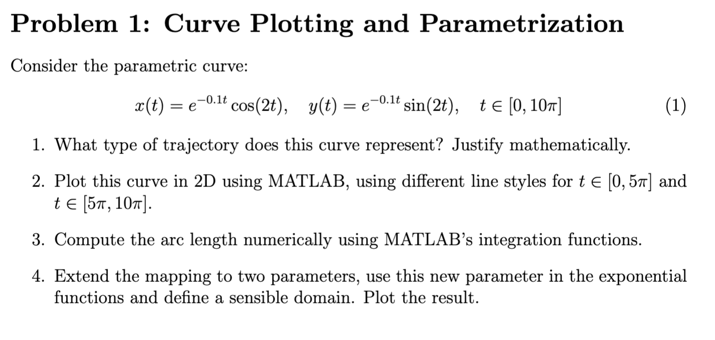

% 1.
x = @(t) exp(-0.1*t) .* cos(t);
y = @(t) exp(-0.1*t) .* sin(t);

% 2.
dx = @(t) -0.1 * exp(-0.1*t) .* cos(t) - exp(-0.1*t) .* sin(t);
dy = @(t) -0.1 * exp(-0.1*t) .* sin(t) + exp(-0.1*t) .* cos(t);
L = integral(@(t) sqrt(dx(t).^2 + dy(t).^2), 0, 10*pi);
disp(['Longitud de arco: ', num2str(L)]);

% 3.
t = linspace(0, 2*pi, 500);
plot(x(t), y(t), 'b', 'LineWidth', 2);
axis equal;
grid on;
title('Curva paramétrica 2D');
xlabel('x(t)');
ylabel('y(t)');

% 4.
z = @(t) t / pi;
figure;
plot3(x(t), y(t), z(t), 'r', 'LineWidth', 2);
grid on;
title('Curva paramétrica 3D');
xlabel('x(t)');
ylabel('y(t)');
zlabel('z(t)');